# **Question 1(c)**

#### **plot of sigma P**

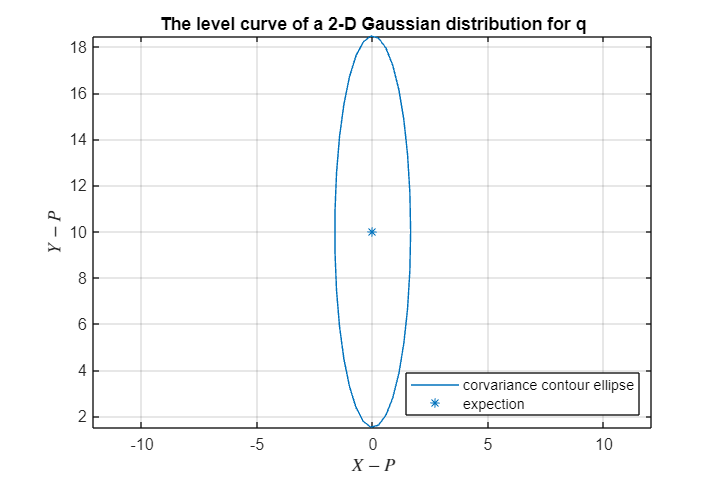

clear all
clc
mu_p=[0;10];sigma_p=[0.3 0;0 8];A=[1 0.5;0 1];b=zeros(2,1);

%Call your function.
xy_p = sigmaEllipse2D(mu_p, sigma_p);

%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure('Position',[300 300 600 400]);

h1 = plot(xy_p(1,:), xy_p(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
hold on
%Also plot a star where the mean is, and make it have the same color as the ellipse.
xlabel('$X-{P}$', 'Interpreter','latex') % Set x-axis label
ylabel('$Y-{P}$', 'Interpreter','latex') % Set y-axis label
title(' The level curve of a 2-D Gaussian distribution for q ')
grid on ;
plot(mu_p(1), mu_p(2), '*', 'color', h1.Color);
legend('corvariance contour ellipse','expection','location','southeast')
hold off

#### plot of sigma P

[mu_z, sigma_z] = affineGaussianTransform(mu_p, sigma_p, A, b)

mu_z =      5
    10


sigma_z =     2.3000    4.0000
    4.0000    8.0000


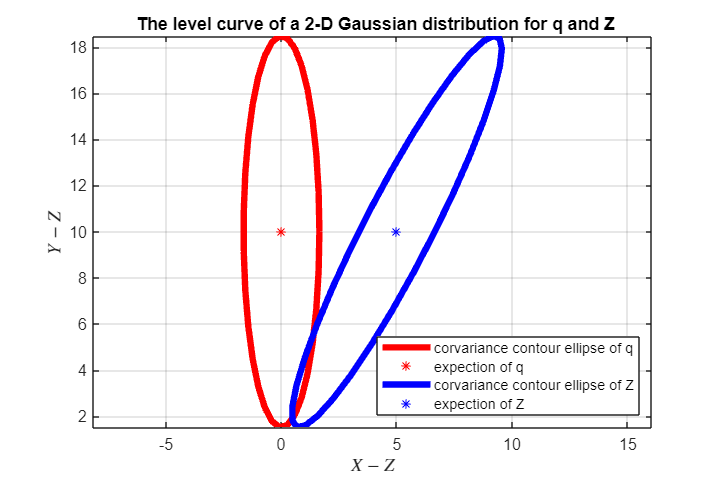

xy_z = sigmaEllipse2D(mu_z, sigma_z);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
plot(xy_p(1,:), xy_p(2,:),'Color','red','LineWidth',4);
hold on
plot(mu_p(1), mu_p(2),'*', 'color', 'red');
hold on
plot(xy_z(1,:), xy_z(2,:),'Color','blue','LineWidth',4);
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.
axis equal
%Also plot a star where the mean is, and make it have the same color as the ellipse.
xlabel('$X-{Z}$', 'Interpreter','latex') % Set x-axis label
ylabel('$Y-{Z}$', 'Interpreter','latex') % Set y-axis label
title(' The level curve of a 2-D Gaussian distribution for q and Z')
grid on ;
hold on
plot(mu_z(1), mu_z(2), '*', 'color', 'blue');
legend('corvariance contour ellipse of q','expection of q','corvariance contour ellipse of Z','expection of Z','location','southeast')
hold off

# Question2(a)


mu_x2=0;sigma_x2=2;

A2=3;b2=0;f=@(x)(3*x);N=1000;
[mu_z2, sigma_z2] = affineGaussianTransform(mu_x2, sigma_x2, A2, b2)

mu_z2 = 0

sigma_z2 = 18

[mu_z3, sigma_z3, y_z3] = approxGaussianTransform(mu_x2, sigma_x2, f, N)

mu_z3 = -0.0996

sigma_z3 = 17.2521

y_z3 =     0.5252   -0.8839    3.4361    2.9074   -0.0516    4.8924    1.6914   -4.5961   -3.5570   -1.0826    3.2343    2.3476   -5.8568   -4.0359    1.0534    1.9676    3.2931   -5.6071    2.4141   -4.0500    7.0944    0.3905    2.3895   -1.7710    3.4557   -0.0490   -3.5215    2.3312   -4.1137   -4.9300   -0.3354    5.1497    1.9956    1.7292    5.9098   -3.2082    1.7356   -5.2742   -9.2127   -2.6275   -0.0523    2.6856    2.5812   -1.0855    3.5566    2.2956    4.9248    2.4610    2.4236    0.4264


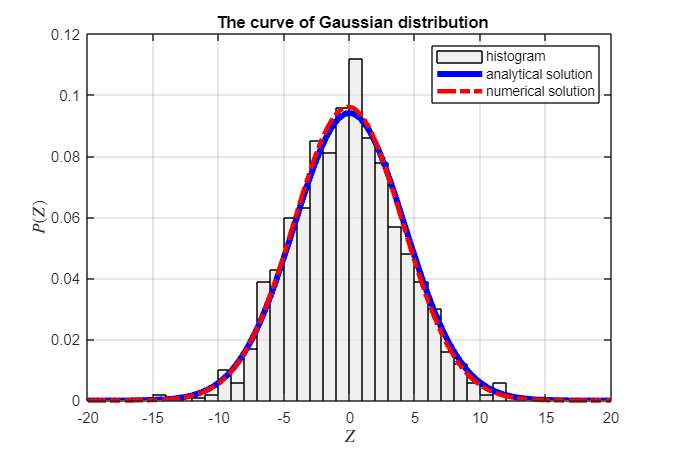

figure('Position',[300 300 600 400]);
histogram(y_z3,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x=[-20:0.1:20];
y=normpdf(x,mu_z2,sqrt(sigma_z2));
plot(x,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x,mu_z3,sqrt(sigma_z3));
plot(x,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')
xlabel('$Z$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Z)$', 'Interpreter','latex') % Set y-axis label
grid on
title(' The curve of Gaussian distribution')

A2=3;b2=0;f=@(x)(3*x);N=5000;
[mu_z2, sigma_z2] = affineGaussianTransform(mu_x2, sigma_x2, A2, b2)

mu_z2 = 0

sigma_z2 = 18

[mu_z3, sigma_z3, y_z3] = approxGaussianTransform(mu_x2, sigma_x2, f, N)

mu_z3 = -0.0075

sigma_z3 = 17.5370

y_z3 =     6.4325   -0.0904    0.4120    1.3366    1.6313   -1.7831    3.8563    2.7740    1.9693   -5.7329    2.9541    0.1499   -8.3460   -1.5001    3.0449    4.1719    1.1648   -0.0972    5.8499    7.4928   -1.5565    1.3914    7.9677   -4.2478   -1.4403    1.0744    1.6004   -6.3796   -0.4563   -1.7651    5.5783    8.4801    1.6085    8.9242   -1.0048    0.7465   -4.1408    0.8224    6.5425   -2.4324    3.0028   -0.0390   -0.7553    2.6933   10.2825   -3.6245    0.7949   -2.0919   -5.2627   -5.4696


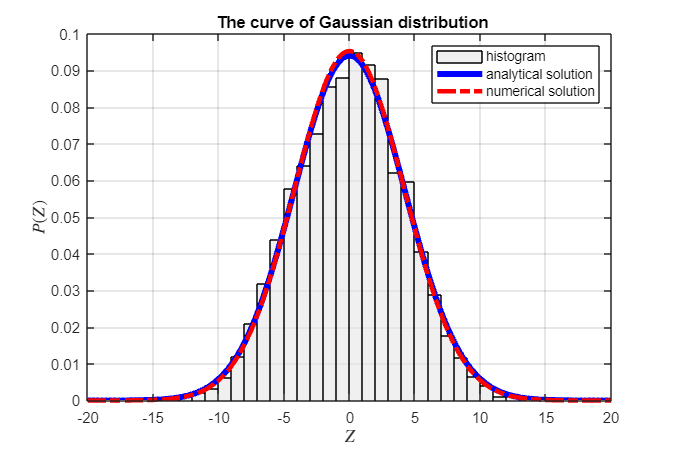

figure('Position',[300 300 600 400]);
histogram(y_z3,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x=[-20:0.1:20];
y=normpdf(x,mu_z2,sqrt(sigma_z2));
plot(x,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x,mu_z3,sqrt(sigma_z3));
plot(x,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')
xlabel('$Z$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Z)$', 'Interpreter','latex') % Set y-axis label
grid on
title(' The curve of Gaussian distribution')

A2=3;b2=0;f=@(x)(3*x);N=50000;
[mu_z2, sigma_z2] = affineGaussianTransform(mu_x2, sigma_x2, A2, b2)

mu_z2 = 0

sigma_z2 = 18

[mu_z3, sigma_z3, y_z3] = approxGaussianTransform(mu_x2, sigma_x2, f, N)

mu_z3 = 0.0257

sigma_z3 = 18.0006

y_z3 =     1.8547   -1.2900    0.4860    1.6218    3.0453   -5.3885    0.2455   -2.6868    3.2942    0.0844   -2.0012    3.1619    3.0183    7.8168   -6.5225    2.7359    3.6688    2.0029   -1.5998    1.7574   10.4484    0.8704   -0.6444    1.6249    3.9635   -0.3501   -6.2113    2.9854   -1.4787   -5.5579   -2.7581   -6.1255    3.1914    2.9037   -7.9461    7.0265    0.0543   -1.9224   -7.2351   -8.1669    0.7575   -0.2969   -4.7766    8.6241    1.9695   -3.7275   -3.1116   -8.8703    4.5698   -7.4505


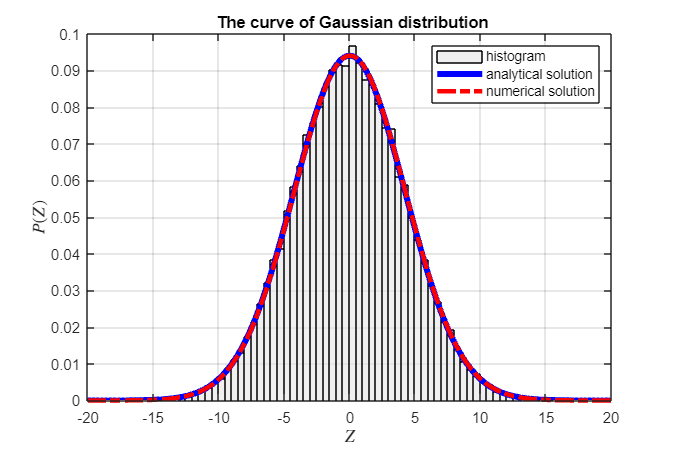

figure('Position',[300 300 600 400]);
histogram(y_z3,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x=[-20:0.1:20];
y=normpdf(x,mu_z2,sqrt(sigma_z2));
plot(x,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x,mu_z3,sqrt(sigma_z3));
plot(x,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')
xlabel('$Z$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Z)$', 'Interpreter','latex') % Set y-axis label
grid on
title(' The curve of Gaussian distribution')

A2=3;b2=0;f=@(x)(3*x);N=100000;
[mu_z2, sigma_z2] = affineGaussianTransform(mu_x2, sigma_x2, A2, b2)

mu_z2 = 0

sigma_z2 = 18

[mu_z3, sigma_z3, y_z3] = approxGaussianTransform(mu_x2, sigma_x2, f, N)

mu_z3 = -0.0044

sigma_z3 = 18.0674

y_z3 =     0.2160    3.0418   -0.1753   -3.5037    4.6824   12.1450    5.6977    5.0088   -2.8722    1.9457   -0.6965    5.0362   -1.4539    4.6828    3.4505    4.2303    7.4569    7.4298   -3.0709   -2.2826   -3.9100    0.1014    1.1036   -1.0772   -3.8816    1.4047    0.4579    1.6118    3.9766   -0.1361   -1.7427   -7.9767   -4.5314   10.4587   -6.8132   -0.2088   -0.9967   -0.0591   -1.4071   -8.0442   -3.0608    6.4817    2.8794  -10.5226    4.8519   -4.3237    2.1145   -2.6086   -0.6539    3.8277


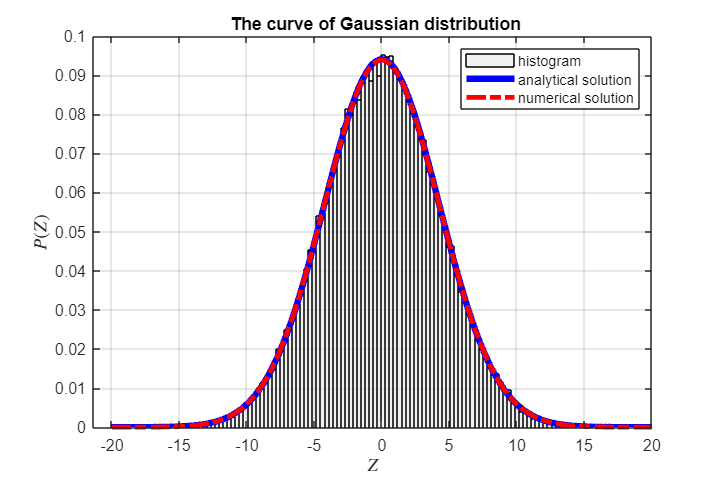

figure('Position',[300 300 600 400]);
histogram(y_z3,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x=[-20:0.1:20];
y=normpdf(x,mu_z2,sqrt(sigma_z2));
plot(x,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x,mu_z3,sqrt(sigma_z3));
plot(x,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')
xlabel('$Z$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Z)$', 'Interpreter','latex') % Set y-axis label
grid on
title(' The curve of Gaussian distribution')

# Question2(b)

f2=@(x)(x^3);N=100000;

mu_z4 = -0.0144

sigma_z4 = 120.4969

y_z4 =    -1.0461    1.0736    3.0000    2.9285   -0.6562   -1.7847    0.8543    2.4180   -0.0999   -5.9237   -0.0574   17.0820    0.0010   -0.0008  -41.0143    0.1007    5.2403    3.2204    0.0282   -0.6639    3.1927    1.0547   -0.0021   -3.1715   -2.4868   -0.1638   -0.3788   -0.1198  -36.0468   -0.0425    5.5026  -24.8294  -11.9296    0.4886   -0.0403   -2.9060   -0.8832    0.4200   24.3388   -0.0000    8.2379    0.1564   -8.2703    6.8498    0.0053   -1.8165   -6.8492   -9.8712    0.1029   13.8179


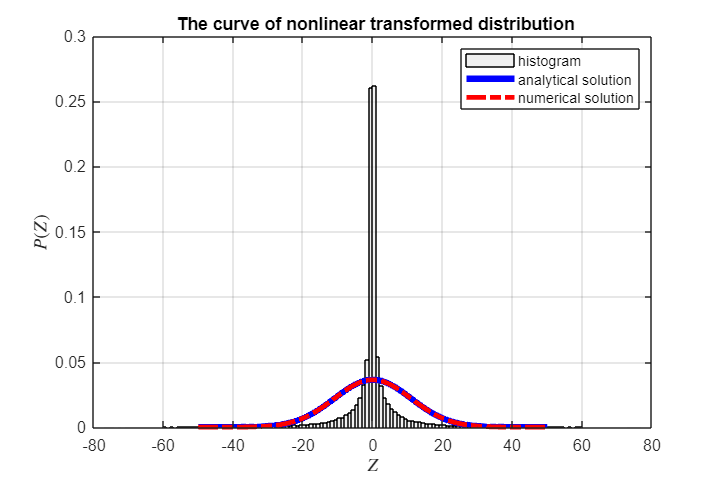

[mu_z4, sigma_z4, y_z4] = approxGaussianTransform(mu_x2, sigma_x2, f2, N)
figure('Position',[300 300 600 400]);
histogram(y_z4,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x1=[-50:0.1:50];
xlim([-80,80])
y=normpdf(x1,0,sqrt(120));
plot(x1,y,'LineWidth',4,'color','blue')
hold on
y=normpdf(x1,mu_z4,sqrt(sigma_z4));
plot(x1,y,'LineStyle','-.','color','red','LineWidth',3)
legend('histogram','analytical solution','numerical solution')
xlabel('$Z$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Z)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution')
grid on
%nonlinear transform, not a Gaussian
hold off

# Question3

# P(y)

clear all

N=100000;
H21=@(x)(4*x);%linear function
a=10;b=20;
x31=[-200:1:200];
%assume sigma_r^2=25
X_uni=a+(b-a)*rand(1,N)%get samples using uniform distribution

X_uni =    16.2622   17.3946   15.8771   17.8166   18.3008   19.0132   12.0023   19.7283   17.8210   13.4621   18.9947   12.6666   16.0728   16.5060   11.9324   18.2444   10.5899   15.2143   11.7253   16.6211   10.2611   15.4125   16.7522   14.3420   10.2725   17.8213   17.0915   14.6472   13.2758   17.7903   13.3877   18.0589   15.6972   10.2958   15.6816   17.1870   18.4030   16.2147   13.1999   13.5919   18.3769   14.8209   18.5153   19.6753   15.1870   13.6204   16.8952   17.0240   12.8978   14.7604


r=mvnrnd(0, 25,N)'%get samples using normal distribution

r =     2.8493   -2.0744    4.3506   -5.8841   -1.7526    8.3422    4.7507   -3.0004   -1.6163   -3.0767    2.3921   -9.4581    0.8854    1.5120   -1.0533   -1.4880    3.3282    4.2504    0.3247    3.5916   -2.6186   -3.8540   -1.3289    1.3173   -7.1784    0.7135    6.3301    8.3124   -7.4294   -1.8234    1.8900    3.0240    1.7039    6.7717    1.1922   -0.4881    2.3639   -6.2183    2.7199   -1.7741   -7.4723   -1.0449    3.3451   -6.5244    2.4718   -8.8344    1.8426    2.1843   -0.0326   -8.3972


% X_uni=unifpdf(x31,-20,20)
ys_3111=[];
for i=1:N
    ys_3111=[ys_3111,H21(X_uni(:,i))];%if it is uniform
end
ys31=[1 1]*[ys_3111;r];
figure('Position',[300 300 600 400]);
histogram(ys31,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
% figure()
% plot(normys31)
hold on
y=[0:0.1:100]

y =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


func=-(erf(8-y/5)+erf((y-80)/5))/(80)

func =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


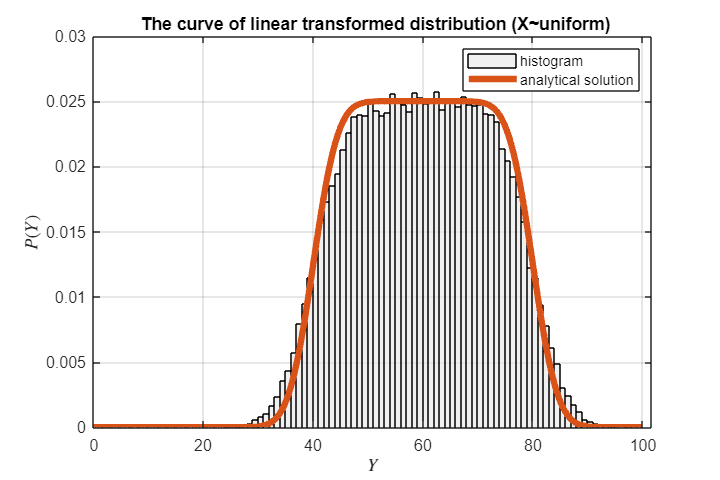

plot(y,func,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of linear transformed distribution (X~uniform)')
grid on
hold off

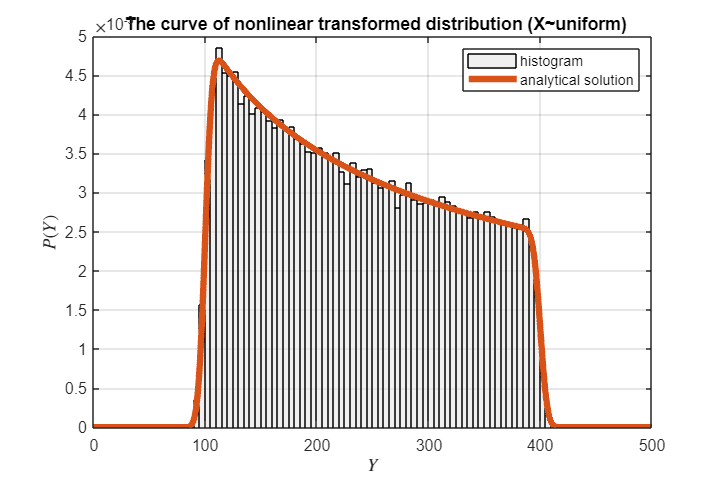

%Integrate[1/10*(1/(sqrt(2*pi*5^2)))*exp(-(y-x^2)^2/2*5^2),{x,10,20}]
H31=@(x)(x.^2);%nonlinear function
ys_3222=[];
for i=1:N
    ys_3222=[ys_3222,H31(X_uni(:,i))];%if it is uniform
end
ys32=[1 1]*[ys_3222;r];
figure('Position',[300 300 600 400]);
histogram(ys32,'Normalization','pdf','FaceColor',[.9 .9 .9]) 

Y=linspace(0,500,5000);
ys_analys=[];
for y=Y
    func=@(x) unifpdf(x,a,b).*normpdf(y,H31(x),5);
    ys_analys=[ys_analys integral(func,a,b)];
end
hold on
plot(Y,ys_analys,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution (X~uniform)')
grid on
hold off

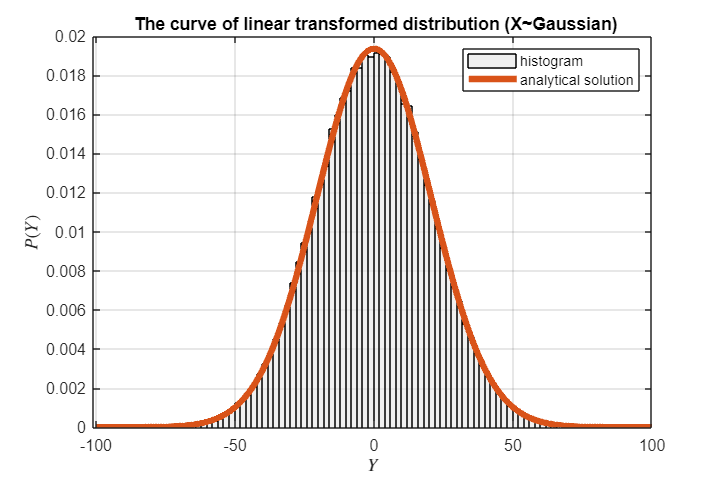

X_normal=mvnrnd(0, 25,N)';
ys_3333=[];
for i=1:N
    ys_3333=[ys_3333,H21(X_normal(:,i))];%if it is uniform
end
ys33=[1 1]*[ys_3333;r];
figure('Position',[300 300 600 400]);
histogram(ys33,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x_normal3=[-100:0.1:100];
y=normpdf(x_normal3,0,sqrt(425));
plot(x_normal3,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of linear transformed distribution (X~Gaussian)')
grid on
hold off

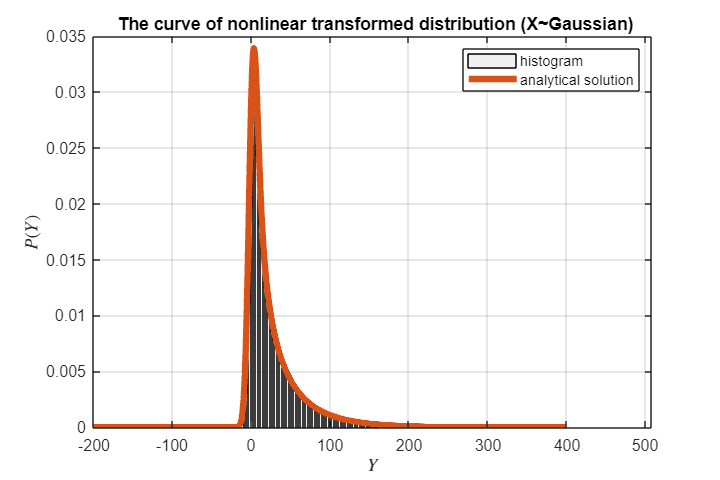

ys_3444=[];
for i=1:N
    ys_3444=[ys_3444,H31(X_normal(:,i))];%if it is uniform
end
ys34=[1 1]*[ys_3444;r];
figure('Position',[300 300 600 400]);
histogram(ys34,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on

Y=linspace(-200,400,5000);
ys_analys=[];
for y=Y
    func=@(x) normpdf(x,0,5).*normpdf(y,H31(x),5);
    ys_analys=[ys_analys integral(func,-15,15)];
end
hold on
plot(Y,ys_analys,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution (X~Gaussian)')
grid on
hold off

# P(y|x)

%%%%%%uniform linear
X_rand=a+(b-a)*rand;
y_31pyx=r+H21(X_rand);
figure('Position',[300 300 600 400]);
histogram(y_31pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
hold on
x_normalyx1=[0:0.1:95];
y=normpdf(x_normalyx1,H21(X_rand),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


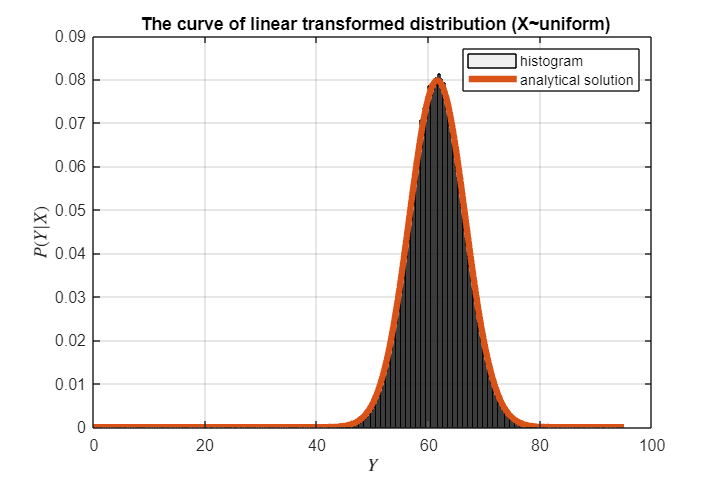

plot(x_normalyx1,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|X)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of linear transformed distribution (X~uniform)')
grid on
hold off

%%%%%%uniform nonlinear
y_32pyx=r+H31(X_rand);
figure('Position',[300 300 600 400]);
histogram(y_32pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx2=[0:0.1:250];
y=normpdf(x_normalyx2,H31(X_rand),sqrt(25))

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


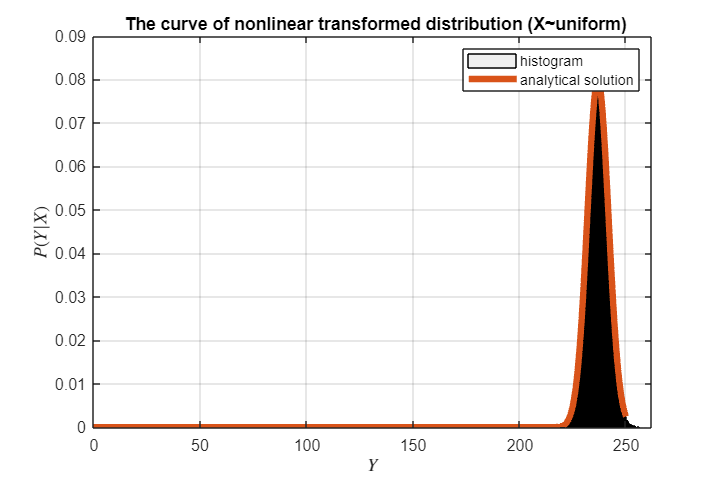

hold on
plot(x_normalyx2,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|X)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution (X~uniform)')
grid on
hold off

X_randn=mvnrnd(0, 25,1);

%%%%%%guassian linear
y_33pyx=r+H21(X_randn);
figure('Position',[300 300 600 400]);
histogram(y_33pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx3=[-100:0.1:50];
hold on
y=normpdf(x_normalyx3,H21(X_randn),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


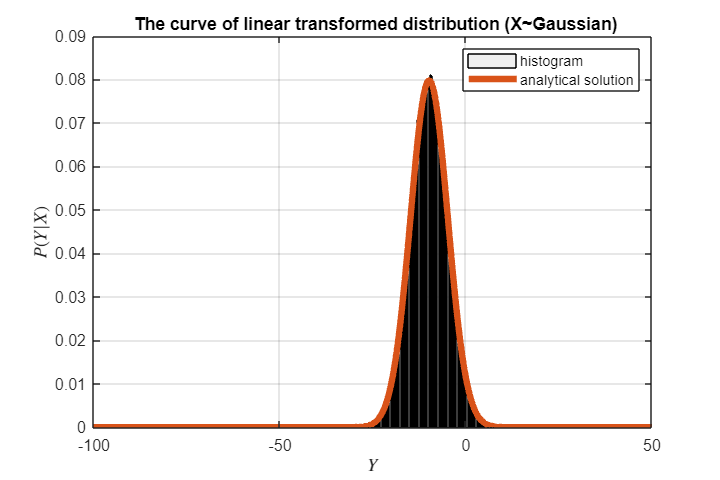

plot(x_normalyx3,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|X)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of linear transformed distribution (X~Gaussian)')
grid on
hold off

%%%%%%guassian nonlinear
y_33pyx=r+H31(X_randn);
figure('Position',[300 300 600 400]);
histogram(y_33pyx,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
x_normalyx4=[-50:0.1:50];

hold on
y=normpdf(x_normalyx4,H31(X_randn),sqrt(25))

y =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


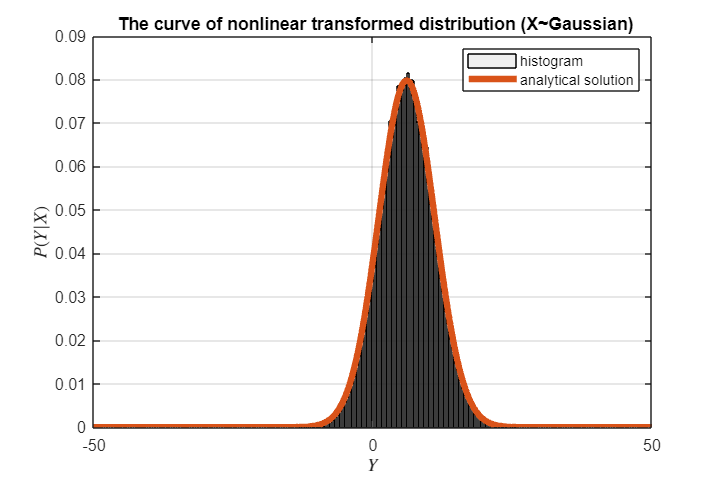

plot(x_normalyx4,y,'LineWidth',4)
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y|X)$', 'Interpreter','latex') % Set y-axis label
title(' The curve of nonlinear transformed distribution (X~Gaussian)')
grid on
hold off

# Question4

sigma41=0.5^2;
N=100000;
x41=[-4:0.1:4];
y41=0.5*normpdf(x41,-1,sqrt(sigma41))+0.5*normpdf(x41,1,sqrt(sigma41));
figure('Position',[300 300 600 400]);
plot(x41,y41,'LineWidth',4);
hold on
w=(mvnrnd(0,sigma41,N))'

w =     0.4288    0.3969   -1.0717   -0.1690   -1.7514   -0.1375   -0.3393    0.9806   -0.3649   -0.1115    0.2913    0.2138   -0.6930   -0.8561    0.4656    0.4484   -0.7012   -0.0885    0.0351    0.2813   -0.6005    0.1053   -0.6401   -0.2591   -0.5402    0.0111    0.0658    0.0319   -0.5325    0.0055    0.7898   -0.5118    0.0236    0.4652    0.6441    0.4144   -0.8096    0.0947    0.5784   -0.0003   -1.0752    0.0992    0.4212    0.4808   -0.0062    0.1205   -0.2804   -0.3984    0.5089   -0.5050


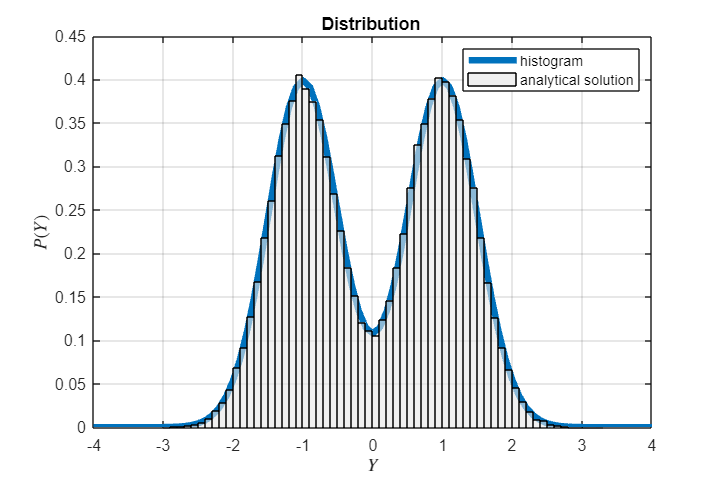

y42=[];
for i=1:N
    random_bit = randi([0, 1], 1, 1);
    if random_bit == 0
        theta = -1;
        y42=[y42 theta+w(i)];
    else
        theta = 1;
        y42=[y42 theta+w(i)];
    end
end
histogram(y42,'Normalization','pdf','FaceColor',[.9 .9 .9]) 
legend('histogram','analytical solution')
xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$P(Y)$', 'Interpreter','latex') % Set y-axis label
title('Distribution ')
grid on
hold off


y47=[-1.98:0.01:1.98];
theta_MMSE=[];
theta_MAP=[];

for i=1:size(y47,2)
    theta_MMSE=[theta_MMSE,(exp(-2*(y47(i)-1)^2)-exp(-2*(y47(i)+1)^2))/(exp(-2*(y47(i)-1)^2)+exp(-2*(y47(i)+1)^2))];
    if exp(4*y47(i))<1
        theta_MAP=[theta_MAP,-1];
    else
        theta_MAP=[theta_MAP,1];
    end
end
figure('Position',[300 300 600 400]);
plot(y47,theta_MMSE,'LineWidth',4)
hold on
plot(y47,theta_MAP,'LineWidth',4)
grid on
legend('\theta_{MMSE}','\theta_{MAP}','intepreter','latex')

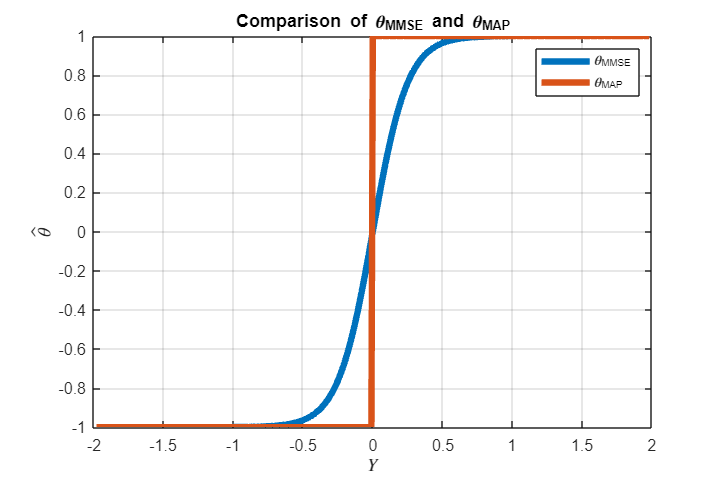

xlabel('$Y$', 'Interpreter','latex') % Set x-axis label
ylabel('$\hat{\theta}$', 'Interpreter','latex') % Set y-axis label
title('Comparison of \theta_{MMSE} and \theta_{MAP}')
hold off

syms y sigma
S=simplify((exp(-(y-1)^2/(2*sigma^2))-exp(-(y+1)^2/(2*sigma^2)))/(exp(-(y-1)^2/(2*sigma^2))+exp(-(y+1)^2/(2*sigma^2))),'Steps',1000)

$$S = 1-\frac{2}{{\mathrm{e}}^{\frac{2\,y}{\sigma^{2}}}+1}$$

filename = fullfile('SensorFusion_ass1_2.m'); % You should change "mainExample.m" with the
copyfile(filename,'SensorFusion_ass1_2.txt','f')

# function

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, npoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
%   MU          [2 x 1] Mean of the Gaussian density
%   SIGMA       [2 x 2] Covariance matrix of the Gaussian density
%   LEVEL       Which sigma level curve to plot. Can take any positive value, 
%               but common choices are 1, 2 or 3. Default = 3.
%   NPOINTS     Number of points on the ellipse to generate. Default = 32.
%
%Output:
%   XY          [2 x npoints] matrix. First row holds x-coordinates, second
%               row holds the y-coordinates. First and last columns should 
%               be the same point, to create a closed curve.


%Setting default values, in case only mu and Sigma are specified.
if nargin < 3
    level = 3;
end
if nargin < 4
    npoints = 32;
end
phi=linspace(0,2*pi,npoints);
xy=zeros(2,npoints);
n=0;
for i=1:npoints
    xy(:,i)=mu+level*sqrtm(Sigma)*[cos(phi(:,i));sin(phi(:,i))];
end
%Your code here
%disp(size(xy,2))
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu_y, Sigma_y] = affineGaussianTransform(mu_x, Sigma_x, A, b)
%affineTransformGauss calculates the mean and covariance of y, the 
%transformed variable, exactly when the function, f, is defined as 
%y = f(x) = Ax + b, where A is a matrix, b is a vector of the same 
%dimensions as y, and x is a Gaussian random variable.
%
%Input
%   MU_X        [n x 1] Expected value of x.
%   SIGMA_X     [n x n] Covariance of x.
%   A           [m x n] Linear transform matrix.
%   B           [m x 1] Constant part of the affine transformation.
%
%Output
%   MU_Y        [m x 1] Expected value of y.
%   SIGMA_Y     [m x m] Covariance of y.

%Your code here
    mu_y=A*mu_x+b;%mu_z=E{AX+BY}=A*mu_x+B*mu_y
    Sigma_y=A*Sigma_x*A';%Sigma_z=Cov{AX+BY}=Cov{Ax}+Cov{By}
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu_y, Sigma_y, y_s] = approxGaussianTransform(mu_x, Sigma_x, f, N)
%approxGaussianTransform takes a Gaussian density and a transformation 
%function and calculates the mean and covariance of the transformed density.
%
%Inputs
%   MU_X        [m x 1] Expected value of x.
%   SIGMA_X     [m x m] Covariance of x.
%   F           [Function handle] Function which maps a [m x 1] dimensional
%               vector into another vector of size [n x 1].
%   N           Number of samples to draw. Default = 5000.
%
%Output
%   MU_Y        [n x 1] Approximated mean of y.
%   SIGMA_Y     [n x n] Approximated covariance of y.
%   ys          [n x N] Samples propagated through f


if nargin < 4
    N = 5000;
end

%Your code here
X = mvnrnd(mu_x, Sigma_x,N)';
% disp(size(X,1))
mu=zeros(size(mu_x,1),1);
y_s=[];
for i=1:N
    y_s=[y_s,f(X(:,i))];
end
mu_y=mean(y_s,2);
Sigma_y=(y_s-mu_y)*(y_s-mu_y)'/(N-1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [mu, Sigma] = jointGaussian(mu_x, sigma2_x, sigma2_r)
%jointGaussian calculates the joint Gaussian density as defined
%in problem 1.3a. 
%
%Input
%   MU_X        Expected value of x
%   SIGMA2_X    Covariance of x
%   SIGMA2_R    Covariance of the noise r
%
%Output
%   MU          Mean of joint density 
%   SIGMA       Covariance of joint density
A=[1 0;1 1];b=zeros(2,1);
mu_x=[mu_x,0]';
Sigma_x=[sigma2_x,0;0,sigma2_r];
[mu, Sigma] = affineGaussianTransform(mu_x, Sigma_x, A, b);
%Your code here
end